# Examen RA3L "intro Matlab"      08/11/2021  16h30 -> 18h00

% Nom : ADDA 
% Prénom : SABIR
% Matricule :

On a placé un capteur de position sur une abeille afin de connaître comment l'insecte se déplace dans l'espace pour réaliser, par la suite, un drône pollinisateur. Le capteur de position a mesuré des coordonnées (x,y), en 2D, par lesquelles l'abeille est passée pour poléniser quatre fleurs comme représenté sur la figure ci-dessous.

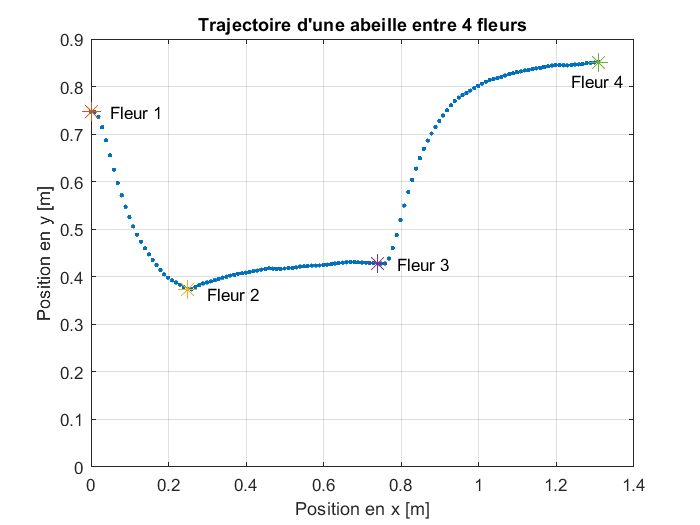

clear all, close all
load data_abeille.mat

**1)** **Récupérez les coordonnées de la trajectoire depuis le fichier "Data_abeille.mat". Sachant que les position (x) des 4 fleurs sont à 0, 0.249m, 0.739m et 1.308m, à quelles hauteurs se trouvent-elles (une solution "manuelle" est exclue) ? Tracez la trajctoire connue et indiquez la position des fleurs comme suit: **(2 points)   *[NB: le repérage des fleurs est un bonus+1]*

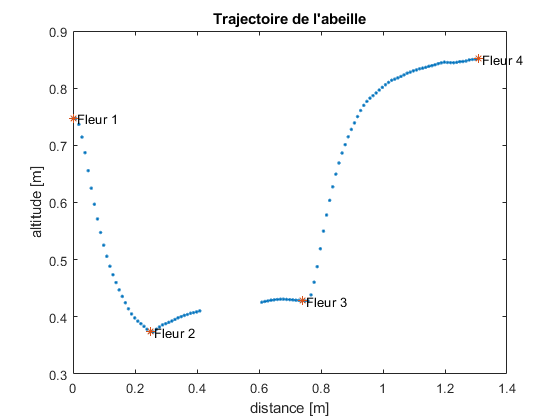

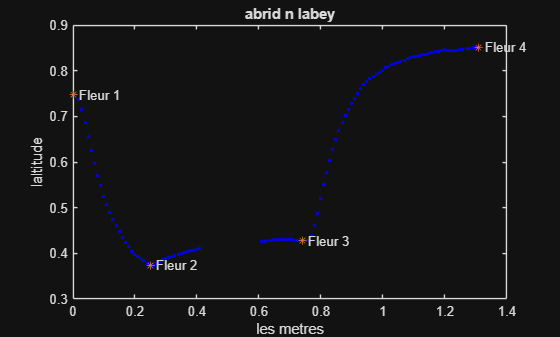

idx1=find(x==0);
idx2=find(x==0.249);
idx3=find(x==0.739);
idx4=find(x==1.308);
x1=[x(idx1) x(idx2) x(idx3) x(idx4)];
y1=[y(idx1) y(idx2) y(idx3) y(idx4)];
%x12=x(idx2);
%x13=x(idx3);
%x14=x(idx4);
%y11=y(idx1);
%y12=y(idx2);
%y13=y(idx3);
%y14=y(idx4);
plot(x,y,'.b',x1,y1,'*')
title('abrid n labey')
xlabel('les metres')
ylabel('laltitude')
for i=1:4
    
    text(x1(i)+0.02,y1(i),sprintf('Fleur %d',i))
end
hold on

**2)** Comme vous l'observez, lors de la mesure, une partie des données a été perdue (entre x=0.409m et x=0.609m). **Estimez les altitudes y manquantes (pour 10 valeurs de x entre 0.409m et 0.609m) par une extrapolation des coordonnées connues via une ****spline****. Tracez-les comme ci-dessous dans le graphique initial **(*2.5 points)*

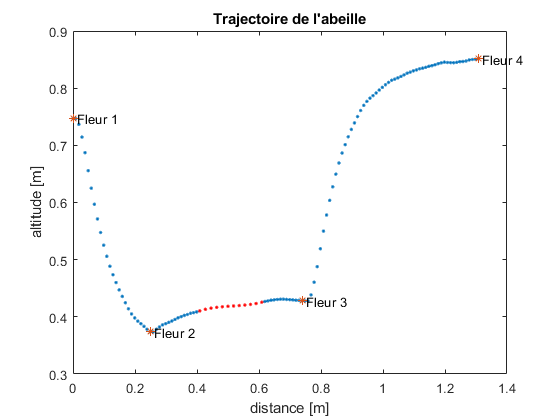

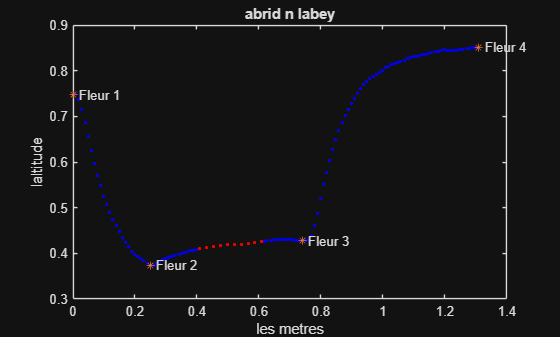

xq=linspace(0.409,0.609,10);
vq = interp1(x,y,xq,'spline','extrap');
plot(xq,vq,'.r')

**3)** Nous souhaitons ensuite ajuster (fiter) une courbe paramétrique sur la trajectoire de la fleur 3 à la fleur 4. Pour ce faire, nous devons ilsoler cette partie de la trajectoire du reste.

**Extrayez les coordonnées (x3, y3) de la trajectoire (x,y) entre la fleur 3 et la fleur 4 (incluses) et décallez ensuite ces coordonnées pour que celles de la fleur 3 soit en (0,0).** (1* points)*

%clf;
x31=x(idx3:idx4);%prendre parcous 3 -4
x3=x31-x31(1);%remettre a 0
y31=y(idx3:idx4);
y3=y31-y31(1);
%plot(x3,y3)

**4)** **Ajustez les 3 paramètres (Xr,A et d) de la ****courbe** $y=\left(x>\textrm{Xr}\right)*A*\left(1-\exp \frac{-\left(x-\textrm{Xr}\right)}{d}\right)$**pour "coller" au sens des moindres carrés à la portion de trajectoire trouvée au point 3 **(si pas trouvée, utilisez x1 et y1 contenus dans fleurs2a3.mat)**, au sens des moindres carrés.** Utilisez 0,1 et 1 comme valeur initiales de Xr, A et d.  (*2.5 points)* 

p=[0 1 1]; %Xr A d
fun1=@(p) (x31>p(1)).*p(2).*(1-exp(-(x31-p(1))./p(3)));

cost1=@(p) norm(y31-fun1(p));

min1=fminsearch(cost1,p);


**5)** **Représentez, sur le graphique initial, la courbe ajustée (aux points x connus) comme ci-dessous**. (*2 points)*

*NB: pensez à replacer votre courbe ajustée à partir de la position de la troisième fleur.*

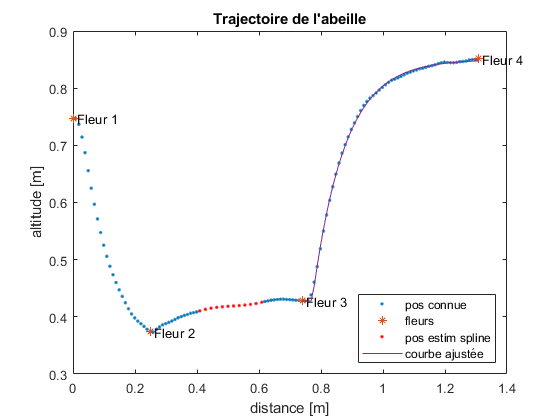

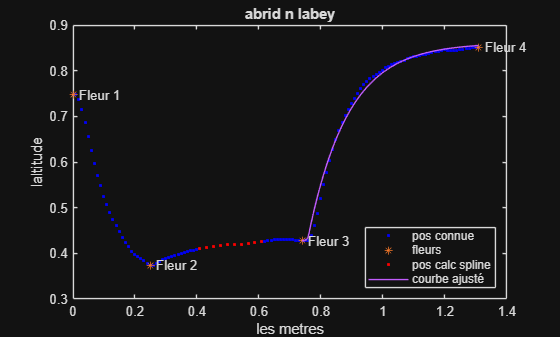


caca=fun1(min1);
caca(1:2)=y31(1:2);
plot(x31,caca)
legend('pos connue','fleurs','pos calc spline','courbe ajusté','Location','southeast')